clear; clc;

## Set parameters

k = 11;      % 2k+1 filter points

N = 2*k+1;
res = 501;                 % resolution
x = linspace(0, 1, res);   % x axis
sample_pos_norm = linspace(0, 1, N+1); % frequency sample position(normalized)
sample_pos_norm = sample_pos_norm(1:N);
sample_pos = round(sample_pos_norm*(res-1)+1);
trans_band = res/2;

## Ideal Hilbert filter

Hd = zeros(1, res) + 1i;
Hd(1:floor(res/2)) = -1i;
Hd(1) = 0;
Hd(ceil(res/2)) = 0;

% plot Hilbert filter
figure;
plot(x, imag(Hd), 'DisplayName', 'Hilbert filter');
xlabel('F');
ylabel('Img');
hold on;

## **Obtain the designed filter**

% step 1. sampling H
R = complex(zeros(1, N));

for m = 1:N
    R(m) = Hd(sample_pos(m));
end

% transition band
tb_weight1 = 0.8;
tb_weight2 = 0.6;
R(2) = tb_weight1*R(2);
R(end) = tb_weight1*R(end);
R(ceil(N/2)) = tb_weight2*R(ceil(N/2));
R(ceil(N/2)+1) = tb_weight2*R(ceil(N/2)+1);

% plot sample points
plot(sample_pos_norm, imag(R), 'o', 'DisplayName', 'sample points');

% step 2. R -(IFT)-> r1
r1 = ifft(R);

% step 3. make the inpulse response "symmetrical"
r = circshift(r1, k);

% step 4. shift r by k
% (not necessary)

% step 5. r -(FT)-> R
H = zeros(1, res);
for f = 1:res
    for n = 1:N
        H(f) = H(f) + (r(n) * exp(-2i*pi*x(f)*(-k+n-1)));
    end
end

## Plot graph

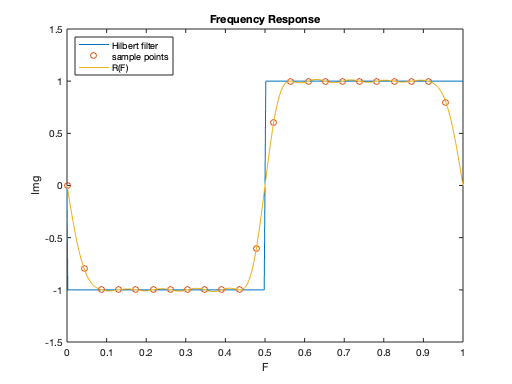

% plot designed filter
plot(x, imag(H), 'DisplayName', 'R(F)');
legend('Location', 'northwest');
title('Frequency Response');
hold off;

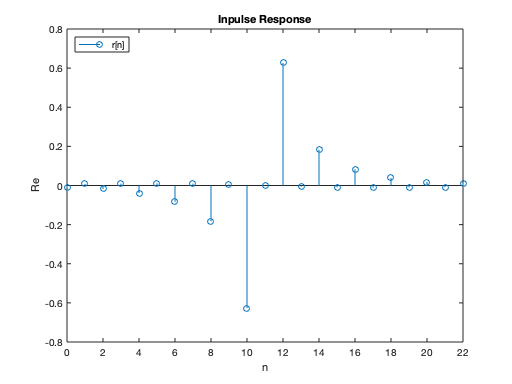

% plot inpulse response
figure;
stem((0:N-1), real(r));
xlabel('n');
ylabel('Re');
xlim([0 N-1]);
legend('r[n]', 'Location', 'northwest');
title('Inpulse Response');